# MA 590 : Computational Inverse Problems

# Homework 7 Part C

## (c)

Changing $d$ from 0.05 to 0.1 results in a very large change in the condition number of $G$ (about $1.54 \times 10^6$ % change or $1.5 \times 10^4$ times the original condition number). The mimimum value of $||x_{\alpha} - x_{true}||$, however, only increased from about 1.2776 to about 1.4225 when computing the regularized Tikhonov solution in part a and we can see that although the corresponding graphs are different that this method held up well considering the large change in condition number of $G$. The regularization parameter, $\alpha$, is not the same. However, while the unregularized solution in part a (original part a) was already of poor quality, this further deteroriated in part c. 

Just as in the original part b, the naive solutions are generally useless. And just as in part a of part c, although these were of poor quality originally, the naive solutions in part b of part c are even worse with the new $G$ matrix. When using the long form data and Tikhonov regularization, we again see that $\alpha$ is the same as in part a of part c (so it's different from the original part a $\alpha$ value but just as in the previous work, $\alpha$ stays consistent from part a to part b - these nested questions are hard to answer!). Also, we again see that the regularized Tikhonov solution is robust with respect to adding this level of noise. So I think we can summarize this as:

Doing things the easy way (unregularized or naive solutions) was always ineffective in this experiment and became even more ineffective as the condition number of $G$ increased. We can recreate the solution well with either choice of $G$ if we commit an inverse crime - but of course the point is that this method is unreliable once we try to apply it to a real problem. Finally, the regularized Tikhonov solution, while imperfect, was resilient when confronted with noise and a high condition number $G$ operator. Both factors decreased the accurary of the solution but by very little with respect to the level of noise (I tried this with higher standard deviation noise to see this) and the large change in condition number of $G$.

## Problem 1

clear all
close all
clc

% 'gravity' test problem: one-dimensional gravity surveying model problem
% (see Regularization Tools for more details)
n   = 64; % size of problem 
ex  = 3;  % type of source function, here step function
s_a = 0;  % interval of s-axis [s_a,s_b]
s_b = 1;
d   = 0.05; % depth

[G,y_true,x_true] = gravity(n,ex,s_a,s_b,d);
d = 0.1;
[Gc,y_true,x_true] = gravity(n,ex,s_a,s_b,d);

K_percent_change = abs(cond(Gc) - cond(G))/cond(G) * 100

K_percent_change = 1.5368e+06

## (a)

G = Gc;

% Modify gravity function to extend length of nonzero source x(t) for t in 
% the interval [-0.5,1.5] (previously, nonzero for t in [0,1])
[~,y_mod,x_mod] = gravity_mod(n,ex,s_a,s_b,d);


[U,S,V] = svd(G);
singular_values = diag(S);

%Testing alpha for 100 logarithmically space points between 10^-1 and 10^2.
%Theses values used because the singular values of G all lie between 10^-1
%and 10^2.
alphas = logspace(-1,2,100);

x_tikhonov = zeros(n, length(alphas));

for jj = 1:length(alphas)
    
    %The filter factors change for each new choice of alpha.
    filter_factors = singular_values.^2 ./ ...
        (singular_values.^2 + (alphas(jj))^2);
    
    %The loop below calculates the Tikhonov solution for a given alpha. 
    for ii = 1:n
        
        x_tikhonov(:,jj) = x_tikhonov(:,jj) + filter_factors(ii) *...
            (U(:, ii))' * y_mod * V(:,ii) / singular_values(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of the residual.
[minnorm, min_index] = min(error_2norms);
minnorm_L0 = minnorm

minnorm_L0 = 1.4225

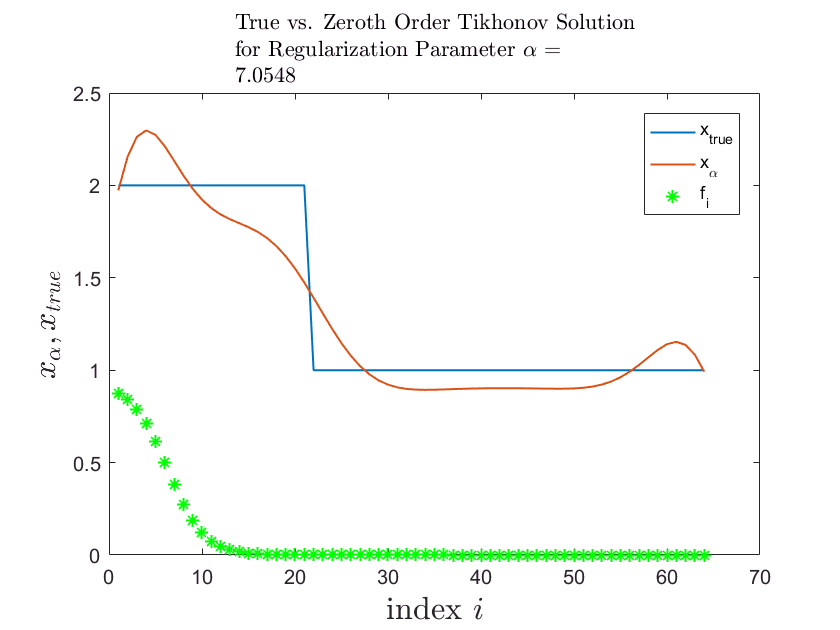

good_alpha = alphas(min_index);
filter_factors = singular_values.^2 ./ ...
        (singular_values.^2 + good_alpha^2);


plot1 = plot(1:n, x_true, 1:n, x_tikhonov(:,min_index), 1:n, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. Zeroth Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{true}', 'x_{\alpha}', 'f_i'};
legend(plot1,names, 'location', 'northeast')

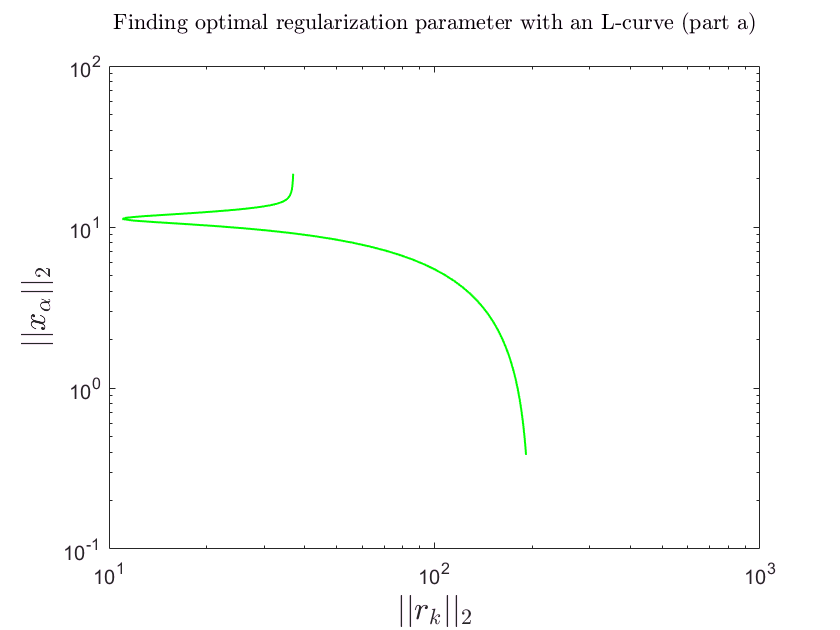

x_alpha_norms = zeros(length(alphas));
residual_2norms = x_alpha_norms;

for ii = 1:length(alphas)

   x_alpha_norms(ii) = norm(x_tikhonov(:,ii));
   residual_2norms(ii) = norm(G*x_tikhonov(:,ii) - y_true);
   
end

plot1= loglog(residual_2norms, x_alpha_norms, 'g', 'linewidth', 1);
xlabel('$$||r_k||_2$$','FontSize',16,'interpreter','latex');
ylabel('$$||x_{\alpha}||_2$$','FontSize',16,'interpreter','latex');
title({'' 'Finding optimal regularization parameter with an L-curve (part a)' ''},'Interpreter','latex')

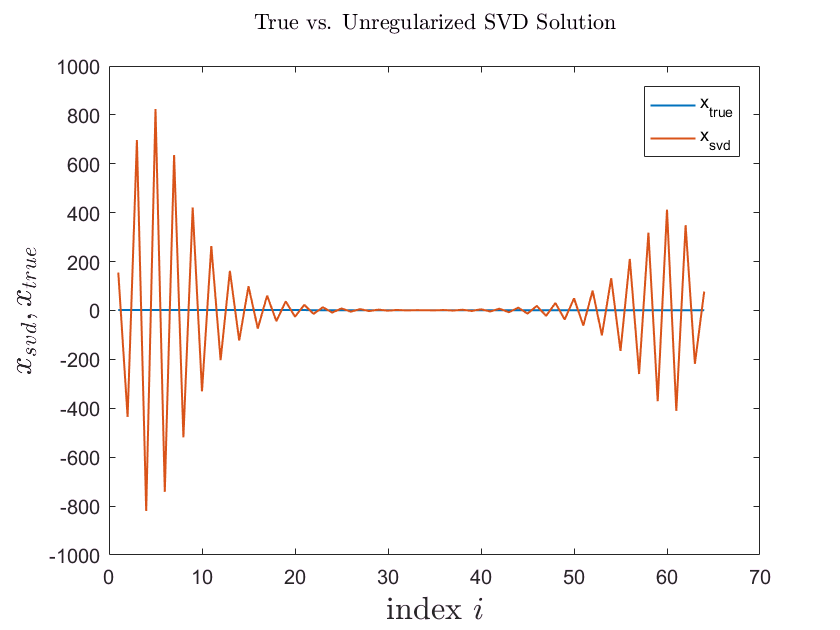

x_unregularized = zeros(n,1);

for ii = 1:n
        
        x_unregularized = x_unregularized + (U(:, ii))' * y_mod * V(:,ii) / singular_values(ii);
      
end

plot1 = plot(1:n, x_true, 1:n, x_unregularized,'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{svd}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. Unregularized SVD Solution' ''},'Interpreter','latex')
names = {'x_{true}','x_{svd}'};
legend(plot1,names, 'location', 'northeast')

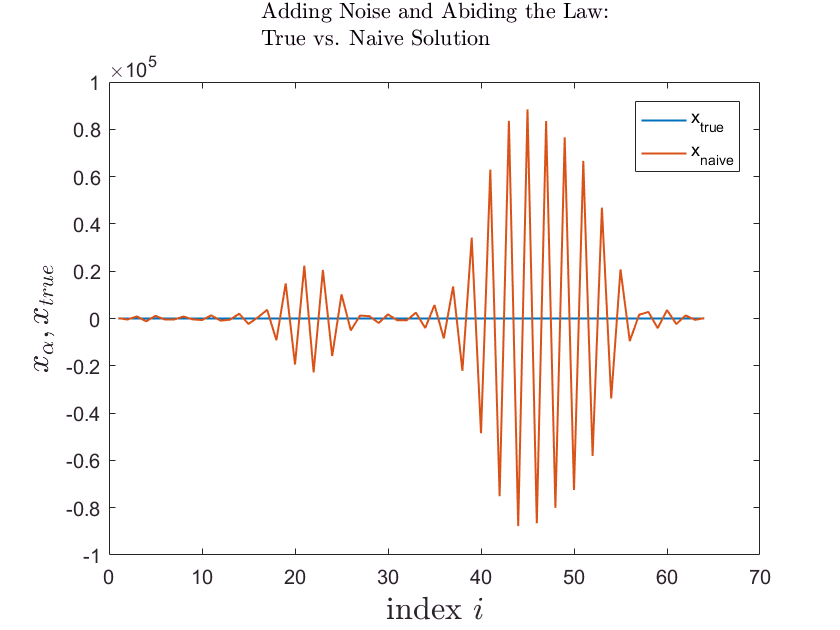

%Using the get_l.m function we apply the process above using L = L_1

[L,W] = get_l(n,1);
[U,V,X,C,S] = gsvd(G,full(L));
Z = (inv(X))';
lambdas = sqrt(diag(C'*C));
mus = sqrt(diag(S'*S));
generalized_singular_values = lambdas ./ mus;

x_tikhonov = zeros(n, length(alphas));

for jj = 1:length(alphas)
    
    filter_factors = zeros(1,n);
    
    %The loop below calculates the Tikhonov solution for a given alpha using equation (3).
    for ii = 1:n
        
        generalized_singular_value = lambdas(ii)/mus(ii);
        
        filter_factors(ii) = generalized_singular_value^2 / ...
            (generalized_singular_value^2 + alphas(jj)^2);
        
        if isfinite(filter_factors(ii)) == 0
            filter_factors(ii) = 1;
        end
        
        % Since G is square, we have k = 0
        % If a generalized singular value is not finite, set the corresponding filter factor to 1.

        x_tikhonov(:,jj) = x_tikhonov(:,jj) + ...
          filter_factors(ii) * (U(:, ii))' * y_mod * Z(:,ii) / lambdas(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of the residual.
[minnorm, min_index] = min(error_2norms);
minnorm_L1 = minnorm;
good_alpha = alphas(min_index);
x_tikhonov_optimal = zeros(n,1);

filter_factors = zeros(1,n);
    
%The loop below calculates the Tikhonov solution for a given alpha using equation (3).
for ii = 1:n
    
    generalized_singular_value = lambdas(ii)/mus(ii);
    
    filter_factors(ii) = generalized_singular_value^2 / ...
        (generalized_singular_value^2 + alphas(jj)^2);
    
    if isfinite(filter_factors(ii)) == 0
        filter_factors(ii) = 1;
    end
    
    % Since G is square, we have k = 0
    % If a generalized singular value is not finite, set the corresponding filter factor to 1.

    x_tikhonov_optimal = x_tikhonov_optimal + ...
      filter_factors(ii) * (U(:, ii))' * y_mod * Z(:,ii) / lambdas(ii);
  
end
    
plot1 = plot(1:64, x_tikhonov_optimal, 1:64, x_true, 1:64, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. First Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{\alpha}' , 'x_{true}', 'f_i'};
legend(plot1,names, 'location', 'northeast');

## (b)

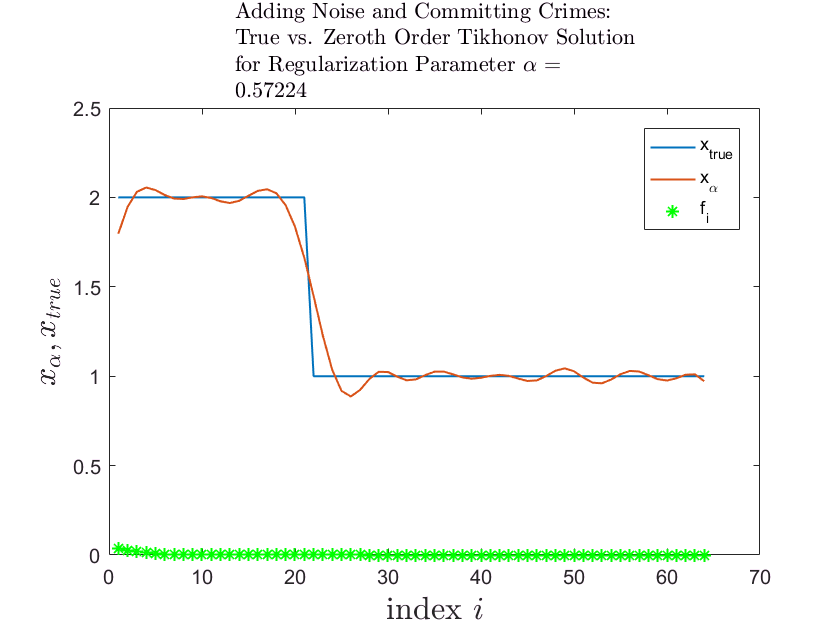

% Part 0 of Part b: Resetting variables
clear all
close all
clc

% 'gravity' test problem: one-dimensional gravity surveying model problem
% (see Regularization Tools for more details)
n   = 64; % size of problem 
ex  = 3;  % type of source function, here step function
s_a = 0;  % interval of s-axis [s_a,s_b]
s_b = 1;
d   = 0.1; % depth

[G,y_true,x_true] = gravity(n,ex,s_a,s_b,d);

% Modify gravity function to extend length of nonzero source x(t) for t in 
% the interval [-0.5,1.5] (previously, nonzero for t in [0,1])
[~,y_mod,x_mod] = gravity_mod(n,ex,s_a,s_b,d);


[U,S,V] = svd(G);
singular_values = diag(S);

%Testing alpha for 100 logarithmically space points between 10^-1 and 10^2.
%Theses values used because the singular values of G all lie between 10^-1
%and 10^2.
alphas = logspace(-1,2,100);

%
%Part 1 of part 1 of part b: Noisy Crimey Data Regularized Solution
%

y_noise = y_true + 10^-1*randn(length(y_true),1);
x_tikhonov = zeros(n,length(alphas));

for jj = 1:length(alphas)
    
    %The filter factors change for each new choice of alpha.
    filter_factors = singular_values.^2 ./...
        (singular_values.^2 + (alphas(jj))^2);
    
    %The loop below calculates the Tikhonov solution for a given alpha. 
    for ii = 1:n
        
        x_tikhonov(:,jj) = x_tikhonov(:,jj) + filter_factors(ii) * ...
            (U(:, ii))' * y_noise * V(:,ii) / singular_values(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of
%the residual.
[minnorm, min_index] = min(error_2norms);
good_alpha = alphas(min_index);

plot1 = plot(1:n, x_true, 1:n, x_tikhonov(:,min_index), 1:n, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'Adding Noise and Committing Crimes:' 'True vs. Zeroth Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{true}','x_{\alpha}' , 'f_i'};
legend(plot1,names, 'location', 'northeast')

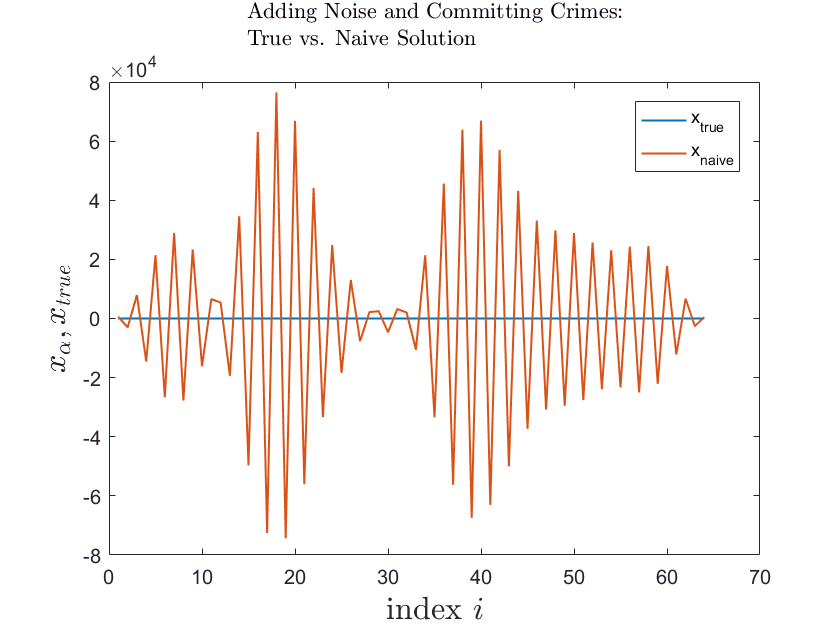


%
% Part 2 of part 1 of part b: Noisy Crimey Data Naive Solution
%

%Calculate the naive solution
x_naive = G \ y_noise;

plot1 = plot(1:n, x_true, 1:n, x_naive,'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'Adding Noise and Committing Crimes:' 'True vs. Naive Solution' ''},...
    'Interpreter','latex')
names = {'x_{true}','x_{naive}'};
legend(plot1,names, 'location', 'northeast')

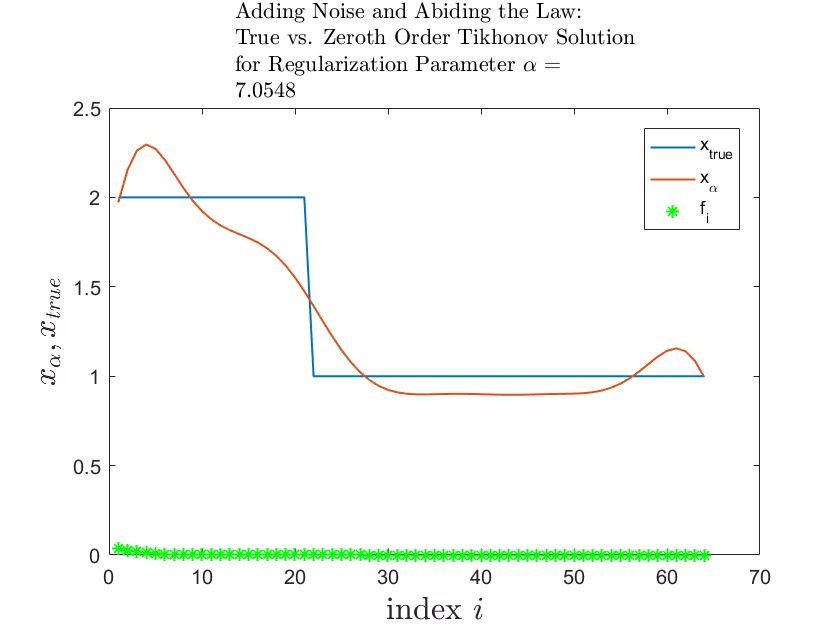


%
%Part 1 of part 2 of part b: Noisy upstanding citizen data regularized solution
%

y_mod_noise = y_mod + 10^-1*randn(length(y_true),1);
x_tikhonov = zeros(n,length(alphas));

for jj = 1:length(alphas)
    
    %The filter factors change for each new choice of alpha.
    filter_factors = singular_values.^2 ./...
        (singular_values.^2 + (alphas(jj))^2);
    
    %The loop below calculates the Tikhonov solution for a given alpha. 
    for ii = 1:n
        
        x_tikhonov(:,jj) = x_tikhonov(:,jj) + filter_factors(ii) *...
            (U(:, ii))' * y_mod_noise * V(:,ii) / singular_values(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of
%the residual.
[minnorm, min_index] = min(error_2norms);
good_alpha = alphas(min_index);

plot1 = plot(1:n, x_true, 1:n, x_tikhonov(:,min_index), 1:n, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'Adding Noise and Abiding the Law:' 'True vs. Zeroth Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{true}','x_{\alpha}' , 'f_i'};
legend(plot1,names, 'location', 'northeast')


%
%Part 2 of part 2 of part b: Noisy upstanding citizen data naive solution
%

%Calculate the naive solution
x_naive = G \ y_mod_noise;

plot1 = plot(1:n, x_true, 1:n, x_naive,'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'Adding Noise and Abiding the Law:' 'True vs. Naive Solution' ''},...
    'Interpreter','latex')
names = {'x_{true}','x_{naive}'};
legend(plot1,names, 'location', 'northeast')